# CornerBot

Classical vs. RL controllers for a reaction-wheel cube.

## Setup

clear; clc;
root = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(root,"functions"), fullfile(root,"simulink"), ...
        fullfile(root,"models"), fullfile(root,"app"));

## Parameters

p = cubeParams();

## Edge: classical check

Gains 190 / 31 / 2.5 / 0.014. Start 1 deg, push at 10 s.

rng(0);
ctrl = @(o) classicalController(o, p.edgeGains, p);
L = simEdge(ctrl, p, 30, 1, [10 0.05 0.05]);
fprintf("Fallen: %d, time up: %.1f s, mean |tilt|: %.2f deg\n", ...
        L.fallen, L.tUp, mean(abs(L.tilt), "omitnan"));

Fallen: 0, time up: 30.0 s, mean |tilt|: 0.08 deg


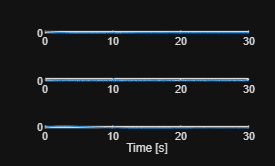


figure;
tiledlayout(3,1);
nexttile; plot(L.t, L.tilt); ylabel("Tilt [deg]"); grid on;
nexttile; plot(L.t, L.u); ylabel("PWM"); grid on;
nexttile; plot(L.t, L.wheel); ylabel("Wheel [rpm]"); xlabel("Time [s]"); grid on;

## Edge: RL training

DDPG, TD3 or SAC. Saves to models/edge<TYPE>.mat.

train = false;
if train
    agent = trainEdgeAgent("DDPG", 1500);
else
    agent = load(fullfile(root, "models", "edgeDDPG.mat")).agent;
end

## Edge: agent check

rng(0);
ctrlRL = agentController(agent, p, rlParams());
L = simEdge(ctrlRL, p, 30, 1, [10 0.05 0.05]);
fprintf("Agent: fallen %d, time up %.1f s, mean |tilt| %.2f deg\n", ...
        L.fallen, L.tUp, mean(abs(L.tilt), "omitnan"));

Agent: fallen 1, time up 0.9 s, mean |tilt| 2.44 deg


## Corner: classical check

Gains 180 / 30 / 1.6 / 0.008, yaw 8 / 0.3

## Corner: RL training

## Evaluation

results = evaluate(controller);

## Demo

CornerBotDemo